# Array Creation Functions

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## TASK 1

x = ones(3, 4)

x =      1     1     1     1
     1     1     1     1
     1     1     1     1


## TASK 2

x = 5*ones(3, 4)

x =      5     5     5     5
     5     5     5     5
     5     5     5     5


## TASK 3

The [`rand`](https://www.mathworks.com/help/matlab/ref/rand.html) function creates a matrix of uniformly distributed random numbers. Random numbers can be useful for creating simulations.

xU = rand(100, 1)

xU =     0.8147
    0.9058
    0.1270
    0.9134
    0.6324
    0.0975
    0.2785
    0.5469
    0.9575
    0.9649


## TASK 4

The [`randn`](https://www.mathworks.com/help/matlab/ref/randn.html) function creates a matrix of *normally* distributed random numbers.

xN = randn(100, 1)

xN =    -1.7947
    0.8404
   -0.8880
    0.1001
   -0.5445
    0.3035
   -0.6003
    0.4900
    0.7394
    1.7119


## TASK 5

The [`randi`](https://www.mathworks.com/help/matlab/ref/randi.html) function creates a matrix of uniformly distributed random integers. Provide the maximum value as the first input, followed by the size of the array you want to create.

`v` `=` `randi``(``maxVal``,``m``,``n``)`

xI = randi(10, 100, 1)

xI =      9
     6
     4
    10
     9
     6
     7
     6
     3
     4


## TASK 6

The uniformly distributed random integers generated by `randi` lie between one and the specified maximum value by default.

You can specify the interval over which the random integers are distributed using

`x` `=` `randi``([``minVal` `maxVal``]``,``m``,``n``)`

This code will generate random integers between `minVal` and `maxVal`

xI2 = randi([11 20], 100, 1)

xI2 =     11
    11
    16
    11
    19
    19
    18
    12
    17
    16


## TASK 7 

The uniformly distributed random numbers generated by `rand` lie between zero and one by default.

The `rand` function doesn't allow you to specify the interval over which the numbers are distributed.

If you want uniformly distributed numbers between values `a` and `b`, you can compute the following:

`x` `=` `a` `+` `(``b``-``a``)``*``rand``(``m``,``n``)`

xU2 = -1 + 2*rand(100, 1)

xU2 =     0.1970
   -0.0582
    0.3919
    0.3998
    0.2771
   -0.9328
   -0.8624
   -0.3608
    0.0617
    0.3089


## TASK 8

Similarly, normally distributed random numbers generated by the `randn` function will have a mean of zero and a standard deviation of one by default.

If you want normally distributed numbers with mean `M` and standard deviation `sd`, you can compute the following:

`x` `=` `M` `+` `sd``*``randn``(``m``,``n``)`

xN2 = 100 + 5*randn(100, 1)

xN2 =   108.6492
   96.9572
   96.3147
   91.2506
  104.5524
  104.3354
   99.6005
  104.4924
  100.9185
  101.4540


## Further Practice

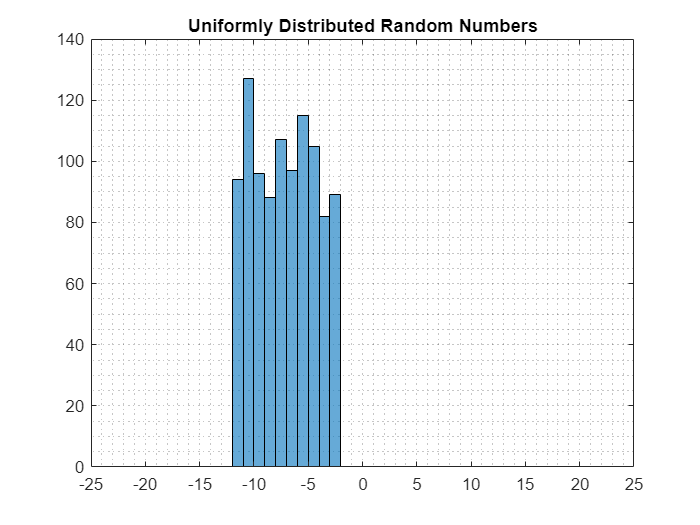

a = -12;
b = -2;
x = a + (b - a) * rand(1, 1000);
histogram(x)
grid minor;
xlim([-25 25])
title("Uniformly Distributed Random Numbers")

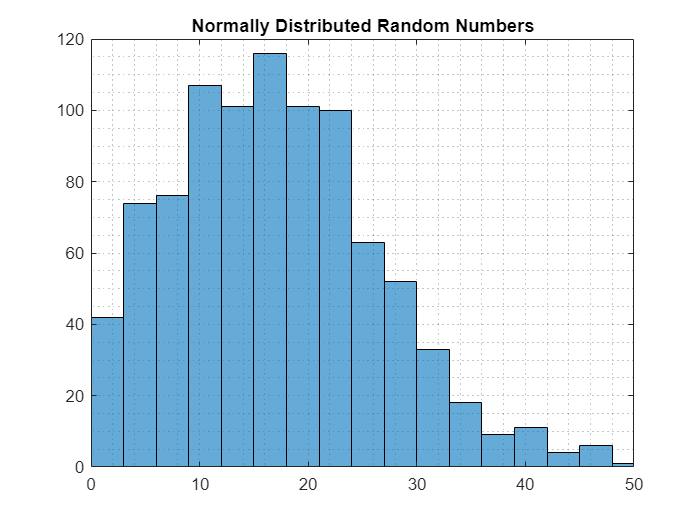


M = 15;
s = 11;
x = M + s * randn(1, 1000);
histogram(x)
grid minor
xlim([0 50])
title("Normally Distributed Random Numbers")